% generate figure 4
% dependence: initRSG2prior, v2struct

### set up

S=initRSG2prior;
v2struct(S); % behDir

### main loop

fig4C


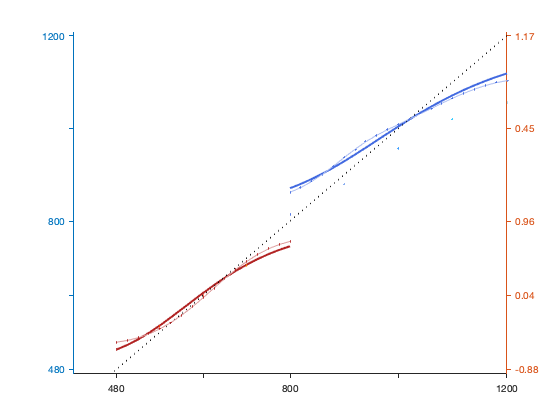

fig4D


fig4D


signrank test ignoring conditions
H0(slope(long)<slope(short)): 0.054688


plot_xu_BLS(S); % fig4CD

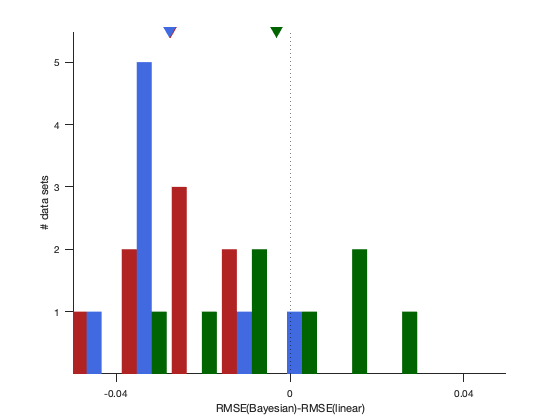

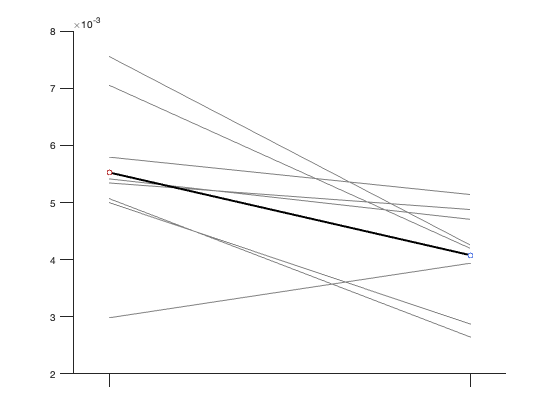

trajKS_tp_EL_G.mat
trajKS_tp_EL_H.mat
trajKS_tp_ER_G.mat
trajKS_tp_ER_H.mat
trajKS_tp_HL_G.mat
trajKS_tp_HL_H.mat
trajKS_tp_HR_G.mat
trajKS_tp_HR_H.mat


fig3g


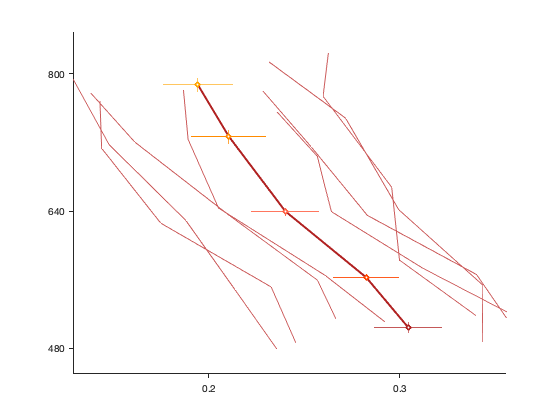

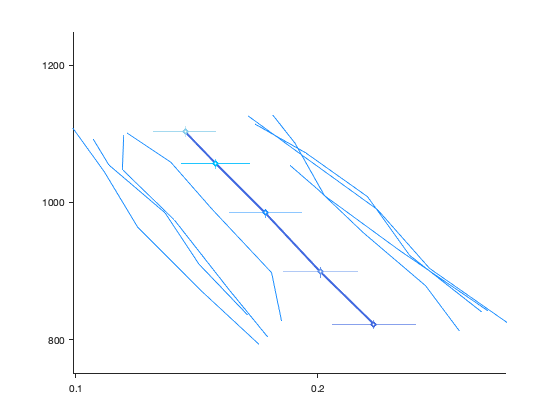

fig3E


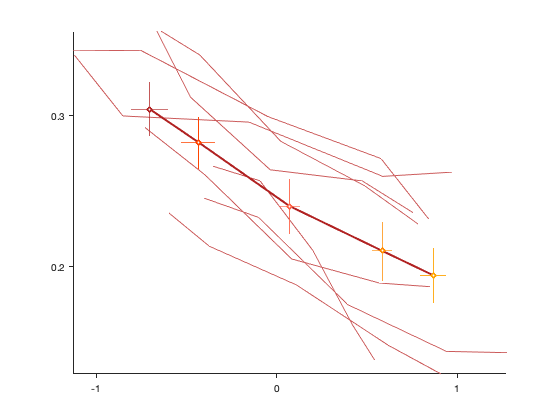

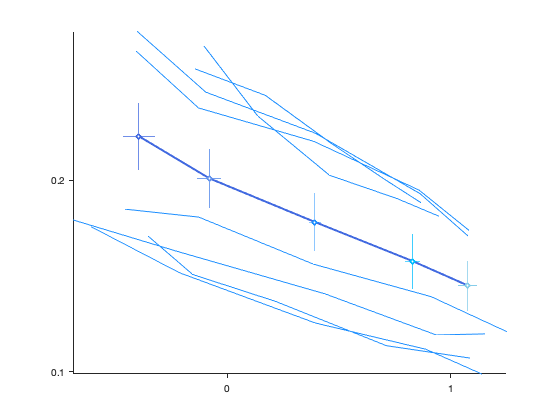


plot_speed_xu_tp(S); % fig4EG


plot_speed0_ts(S); % fig4F: done by Nico



function plot_speed_xu_tp(S) % fig4EG

idNewTraj=1;
idTpMTs=1;  % plot te-ts vs ts

idDebug=0; %1;

idCosyne=0; % 1;

dim=inf; % 3; % 5; % 4; % 2; % 3; %%%%%
useOptimD=1; % 0; % if 1, use optimD
maxDim=10; % tp-specific; H/G, ER/EL/HR/HL: 6 5 7 6 8 9 7 8

isSepPr=0; % : if 1, use separate readout vector for sICa

%% figure setting
try
    load('/Users/hansem/Dropbox (MIT)/commonCode/pplot.mat'); % tmpCmap
catch
    try
        load('/Users/seonminahn/Dropbox (MIT)/commonCode/pplot.mat'); % tmpCmap
    catch
        load pplot.mat; % tmpCmap
    end
end

cmap={pplot.cmap{1}; pplot.cmap{3}; pplot.cmap{5}}; % for short/long/SL
cmap3=[tmpCmap{1,1};tmpCmap{2,1}];

tmpMarker={'^','v','<','>','o','s','d','h'};

    % figure's PaperUnits: 'inches'
    optsExpFig.Height=4.2/2.54; % 2*1.2; % 0.8; % '1.2'; % '2'; % 7;
    optsExpFig.Width=4.2/2.54; % 3.6; % 1.5*1.2*2; % '2.4'; % '4';
    optsExpFig.FontSize='6';
    optsExpFig.FontMode='fixed';
    optsExpFig.Format='eps'; % 'tiff'; % 'pdf'; % 'png';
    optsExpFig.LockAxes=1;
    optsExpFig.LineMode='fixed'; % 'scaled';
    %     optsExpFig.LineWidthMin=0.5;
    %     optsExpFig.LineWidthMax=1.5;
    optsExpFig.LineWidth=.5; %1;
    optsExpFig.Renderer='painters';
    
    lw=1.5;
    lw2=1;
    msize=4; % 5; % 10; % 4;
    msize2=2;
    
    % H/G, E/H, R/L
    cmapHG=[0 0 0; .5 .5 .5]; % animal & E/H
    %     cmapCond={[0 0 0; 1 1 1];
    %         [.5 .5 .5; 1 1 1]};
    markers={'o','^','o','^'};
    
    nCmap=8; % nAnimal*nEH*nTarg;
    cmapCond=parula(nCmap); % hsv(nCmap);
    icmap=1;
    
    cmapPr=[rgb('FireBrick'); rgb('RoyalBlue'); rgb('DarkGreen')]; %
    cmapPr2=[rgb('IndianRed'); rgb('DodgerBlue'); rgb('ForestGreen')]; % for each data set
idExpFig=0; % 0; % 1;
idPlot=0; % for plotTraj (projected onto meas space)

%% initial
v2struct(S);

nTs=nTspp;
try
    cd(psthDir);
catch
    psthDir='/Users/seonminahn/Dropbox (MIT)/psthDataHigh';
    cd(psthDir);
end

binSize=20;
smthWidth=40;
nBins=round([T{1}(:); T{2}(:)]/binSize); % 24 28 ... 60
maxNbin=44; % tp-specific

% speed & arc length (whole meas/overlap)
v=nan(nAnimal,nEH,nTarg,nPr,nTs,maxNbin); % speed [2HG x 2EH x 2RL x 2SL x 5ts x 60timePoints]
vv=nan(nAnimal,nEH,nTarg,nPr,nTs,maxNbin,maxDim); % velocity vector vv(idAnimal,iEH,iTh,idPr,iTs,1:nV,1:dim)[2HG x 2EH x 2RL x 2SL x 5ts x 60timePoints x dim]
v2=nan(nAnimal,nEH,nTarg,nPr,nTs,maxNbin); % ||2nd derivative|| [2HG x 2EH x 2RL x 2SL x 5ts x 60timePoints]
c=nan(nAnimal,nEH,nTarg,nPr,nTs,maxNbin); % curvature [2HG x 2EH x 2RL x 2SL x 5ts x 60timePoints]
nEpoch=1; % 3; % wholeMeas/overlap, short/long, SIL
x=nan(nAnimal,nEH,nTarg,nPr,nTs,nEpoch); % arc length [2HG x 2EH x 2RL x 2SL x 5ts x 60timePoints]

%% kinet (distance between nearest neighbors)
% less noisy (distance is noisy)
% not highly dependent on binSize
% assuming same manifold

% use mean of each prior
refPr=[1 2]; % 2; % 1; % 2;
refTs= round(cellfun(@length,T)/2); % length(T{refPr}); %1; % length(T{refPr}); %1; % length(T{refPr}); % longest of long (overlap)

% speed & distance
sp=nan(nAnimal,nEH,nTarg,nPr,nTs); % [2HG x 2EH x 2RL x 2SL x 5ts]
dist=nan(nAnimal,nEH,nTarg,nPr,nTs); % [2HG x 2EH x 2RL x 2SL x 5ts]

% 1) angle b/t velocity vectors of short vs long as a function of time: if <90, parallel
% 2) shortest path length between short and long: constant?
% 3) angle b/t tangent and shortest path vector: if <90, on the same manifold

% shortest path legnth between short and long: after reaching final state for ts, meaningless
sSp=nan(nAnimal,nEH,nTarg,nPr,nTs,maxNbin,maxDim); % [2HG x 2EH x 2RL x 2SL x 5ts x timePoints]
tSp=nan(nAnimal,nEH,nTarg,nPr,nTs,maxNbin); % [2HG x 2EH x 2RL x 2SL x 5ts x timePoints] in refD's bin unit
spv=nan(nAnimal,nEH,nTarg,nPr,nTs,maxNbin,maxDim); % [2HG x 2EH x 2RL x 2SL x 5ts x timePoints x dim]

% 1) angle b/t velocity vectors of short vs long as a function of time: if <90, parallel
av=nan(nAnimal,nEH,nTarg,nPr,nTs,maxNbin,nPr,nTs); % [2HG x 2EH x 2RL x 2SL x 5ts x timePoints x (2SL x 5ts)]
av2=cell(nAnimal,nEH,nTarg,nPr,maxNbin); % [2HG x 2EH x 2RL x within/betweenPriors x timePoints]
% 2) shortest path length between short and long: constant?
spl=nan(nAnimal,nEH,nTarg,nPr,nTs,maxNbin); % [2HG x 2EH x 2RL x 2SL x 5ts x timePoints]
% 3) angle b/t tangent and shortest path vector: if <90, on the same manifold
aSpvTv=nan(nAnimal,nEH,nTarg,nPr,nTs,2,maxNbin); % [2HG x 2EH x 2RL x 2SL x 5ts x 2tv(ts,ref) x timePoints]


%% tp-specific
tInitCond=200;%400; % 200;
initT=1; % tInitCond/binSize; % 10th bin
t0sv=40/binSize; % given speed profiles: time vector [40 160]
t1sv=160/binSize;

% 1) testing nontrivial prediction: all/many curved neuron respond to set
%     (or in the same subspace as set-responsive neurons), revealing funcitonal role of curved trajectory
%    - angle between ts vector & time vector: orthogonal?                % extract vv from analSpeed_ts?
aTsvSv2=nan(nAnimal,nEH,nTarg,nPr,nTs); % prod-space % [2HG x 2EH x 2RL x 2SL x 5ts x timePoints]; for short800, tsv to long800, for 1200, tsv from 1100
%    - assuming curved trajectory is in 2D (check: scree?), projecting time vector to the 2D plane>angle b/t the projected time vector and rotating vector
aTsvSv1=nan(nAnimal,nEH,nTarg,nPr,nTs); % meas-space
%    - do PCA separately for set and IC: angle between proj_matrix (or CCA?)
%    - regression? how to choose set-responsive neuron?
% 2) check angle/magnitude b/t readout vectors across ts, prior: 2D cmap, if <90, parellel-not state dependent
%    - kinet: nearest distance coalesce during set transient?
asv=nan(nAnimal,nEH,nTarg,nPr*nTs,nPr*nTs);
asv2=cell(nAnimal,nEH,nTarg,nPr); % within/betweenPriors
msv=nan(nAnimal,nEH,nTarg,nPr,nTs);
% 3) curvature b/t Set vs IC (200ms): scatter, separately for short and long
%   - 2D @ set, 1D @ set
% only in meas-subspace as rotation is not clear in prod-subspace
cAcrTs=nan(nAnimal,nEH,nTarg,nPr,2,nTspp-2); % [2HG x 2EH x 2RL x 2SL x @set/@IC x 3data points]

% 1) IC vector size (ref to each prior mean) or their relative angle (more curved?): without finding out nearest neighbors
tsv=nan(nAnimal,nEH,nTarg,nPr*nTs-1,maxDim,maxNbin); % [2HG x 2EH x 2RL x 9 diffTs x time x dim]: for short800, tsv to long800
mtsv=nan(nAnimal,nEH,nTarg,nPr*nTs-2,maxNbin); % magnitude of tsv [2HG x 2EH x 2RL x 9 diffTs x time]: for short800, tsv to long800
atsv=nan(nAnimal,nEH,nTarg,nPr*nTs-1,maxNbin); % angle b/t nearby tsv [2HG x 2EH x 2RL x 9 diffTs x time]: for short800, tsv to long800
% 2) angle b/t overlap vector & time/ts vector: common time-warped axis?
aTsvOv=nan(nAnimal,nEH,nTarg,nPr*nTs-2,maxNbin);
aVvOv=nan(nAnimal,nEH,nTarg,nPr*nTs,maxNbin);% vv=nan(nAnimal,nEH,nTarg,nPr,nTs,maxNbin); % velocity vector [2HG x 2EH x 2RL x 2SL x 5ts x 60timePoints x dim]
% 3) angle/magnitude of time vectors (ref: prior mean)
% use asv, msv
% 4) angle b/t common IC axis
aCommIC=nan(nAnimal,nEH,nTarg,maxNbin);

% available from analSpeed_ts: speed, |2nd derivative|, curvature, kinet
% + angle b/t velocity vectors of short vs long as a function of time: if <90, parallel
% + shortest path length between short and long: constant?
% + angle b/t tangent and shortest path vector: if <90, on the same manifold

%% cosyne
mtp=nan(nAnimal,nEH,nTarg,nPr,nTs); % speed [2HG x 2EH x 2RL x 2SL x 5ts]
sICa=nan(nAnimal,nEH,nTarg,nPr,nTs); % projection of states onto IC axis

xuAll=nan(nAnimal,nEH,nTarg,nPr,nTs);

if idNewTraj
    d_tmp=dir('trajKS_tp_*.mat'); % bin20_smth40>use new tp data set
    jd=1;
    for iD=1:length(d_tmp)
        if ~isempty(regexp(d_tmp(iD).name,'trajKS_tp_\w\w_\w.mat'))
            if jd==1
                d=d_tmp(iD);
            else
                d(jd)=d_tmp(iD);
            end
            jd=jd+1;
        end
    end
else
    d=dir('trajKS_tp_*bin20_smth40.mat'); % bin20_smth40>use new tp data set
end

for iFile=1:length(d)
    %% for all conditions
    nm=d(iFile).name;
    load(nm); % D keep_neurons binSize optimD proj_matrix smthWidth
    %     size(D(10).data) 44
    disp(nm);
    
    if useOptimD % isinf(dim)
        load(nm,'optimD'); dim=optimD;
    end
    
    % finding animal, condition > use that projection
    if idNewTraj
        if ~isempty(strfind(d(iFile).name,'_H.mat'))
            idAnimal=1; iAnimalNm='H';
        else
            idAnimal=2; iAnimalNm='G';
        end
    else
        if ~isempty(strfind(d(iFile).name,'_H_'))
            idAnimal=1; iAnimalNm='H';
        else
            idAnimal=2; iAnimalNm='G';
        end
    end
    if ~isempty(strfind(d(iFile).name,'_ER_'))
        iEH=1; iTarg=1;
    elseif ~isempty(strfind(d(iFile).name,'_EL_'))
        iEH=1; iTarg=2;
    elseif ~isempty(strfind(d(iFile).name,'_HR_'))
        iEH=2; iTarg=1;
    elseif ~isempty(strfind(d(iFile).name,'_HL_'))
        iEH=2; iTarg=2;
    end
    tmpId=[iEH; iTarg];
    
    % load Xu
    load(['trajKS_prior_' nm(11:14) '_avgAttB4PCA.mat'],'Xu'); %{1x3pr} [1x17 1x21 1x17]
    for iPr=1:nPr
        xuAll(idAnimal,iEH,iTarg,iPr,:)=Xu{iPr}(linspace(1,length(Xu{iPr}),nTspp)); % short
    end
    
    epNm={'fixation';'targetOn';'periReady';'periSet';'production';'ts';'tp';'_priorS_';'_priorL_';'_priorSL_';'t_s';'t_p'};
    epNm2={'preFix','postFix';'preTOn','postTOn';'preReady','postReady';'','';'prod','postProd';'','';'','';'','';'','';'','';'','';'',''};
    for i=1:length(epNm)
        if ~isempty(strfind(nm,epNm{i})), break; end;
    end
    idEp=i;
    
    if strfind(nm,'periSet') % trajKS_periSet_ER_H
        idProd=1;
        idMeas=1;
        idAtt=0;
        
        curv=cell(nPr,1);
    elseif strfind(nm,'ts')
        idProd=0; % 1; % plotting together
        idMeas=1; % 0; % 1;
        idAtt=0;
        
        curv=cell(nPr+1,1);
    elseif strfind(nm,'tp')
        idProd=1; % 1; % plotting together
        idMeas=0; % 1; % 0; % 1;
        idAtt=0;
    elseif strfind(nm,'prior')
        idProd=0; % 1; % plotting together
        idMeas=1; % 0; % 1;
        idAtt=0; % 1; % 0; % 1;
        %     if strfind(nm,'priorSL')
        %         idAtt=0;
        %     else
        %     idAtt=1;
        %     end
    end
    
    
    idCondSpecific=true; % false;
    conditionSpecificPCANm={'condSpecPCA'};
    
    %% main
    % condId=1; % eyeRight
    % for iEH=1:nEH
    %     for iTh=1:nTarg
    %         if idCondSpecific
    tmpD=D;iEH=tmpId(1);iTh=tmpId(2);
    %             if iEH>2, iEH=2; end; % E2, H2 avgDir
    %         else
    %             tmpD=D(condId:4:length(D));
    %         end
    
    tmpMin=[]; % for setting measure/produce in the same range
    tmpMax=[];
    
    sv=nan(length(tmpD),dim); % time vector [10ts x optimD]
    
    if idProd % idMeas
        %% production only
        %         hFig=figure;setFigPos(1,1);% set(gcf,'position',pplot.(['rect' num2str(iEH) '_' num2str(2*(iTh-1)+1)]));hold all;
        %         hFig2=figure;setFigPos(1,2);
        %         hFig3=figure;setFigPos(1,3);
        
        %         figure;
        if idDebug
            figure; grid on; % debug
        end
        
        for i=1:length(tmpD) % 10 ts
            if length(tmpD(i).epochStarts)>1
                iSet=tmpD(i).epochStarts(2);
            else
                iSet=size(tmpD(i).data,2);
            end
            idPr=floor((i-1)/nTs)+1; %  1     1     1     1     1     2     2     2     2     2
            iTs=rem(i-1,5)+1;
            
            endPre=1;
            tmpX=tmpD(i).data(1,1:iSet);
            tmpY=tmpD(i).data(2,1:iSet);
            tmpZ=tmpD(i).data(3,1:iSet);
            
            %% speed
            tmp=tmpD(i).data(1:dim,1:iSet); % [dim x time]
            if idDebug,            ha; plot3(tmp(1,:),tmp(2,:),tmp(3,:),'o-','color',tmpCmap{idPr}(iTs,:)); end; % debug \
            tmpV=sqrt(sum(diff(tmp,1,2).^2,1));       % [1 x (time-1)]
            nV=length(tmpV);
            
            v(idAnimal,iEH,iTh,idPr,iTs,1:nV)=tmpV; % [2HG x 2EH x 2RL x 2SL x 5ts x 60timePoints]
            
            %             figure; histogram(tmpV(initT:end),15); title([iAnimalNm ' ' ehNm{iEH} ' ' targNm{iTh} ' ' prNm{idPr} ' ts#' num2str(iTs)]); waitforbuttonpress; close;
            
            vv(idAnimal,iEH,iTh,idPr,iTs,1:nV,1:dim)=diff(tmp,1,2)';
            
            % norm of 2nd derivative
            tmpV2=sqrt(sum(diff(tmp,2,2).^2,1));       % [1 x (time-2)]
            nV=length(tmpV2);
            v2(idAnimal,iEH,iTh,idPr,iTs,1:nV)=tmpV2;
            
            %% arc length
            % wholeMeas/overlap, short, long, SIL
            x(idAnimal,iEH,iTh,idPr,iTs,1)=sum(tmpV); % wholeMeas(longest ts/prior)/overlap(overlap ts/prior)
            
            % 2) check angle/magnitude b/t readout vectors across ts, prior: 2D cmap, if <90, parellel-not state dependent
            %    - kinet: nearest distance coalesce during set transient?
            vTmp=tmp(:,t1sv)-tmp(:,t0sv); % tmp(:,initT)-tmp(:,1);
            sv(i,:)=normalize(vTmp(:),1);
            msv(idAnimal,iEH,iTh,idPr,iTs)=sqrt(sum(vTmp.^2,1));
            
            %% kinet (distance between nearest neighbors)
            % less noisy (distance is noisy)
            % not highly dependent on binSize
            % assuming same manifold
            
            % 1) angle b/t velocity vectors of short vs long as a function of time: if <90, parallel
            % 2) shortest path length between short and long: constant?
            % 3) angle b/t tangent and shortest path vector: if <90, on the same manifold
            
            %%%%% prior mean as refs
            if i>nTs % long prior
                refD=tmpD((refPr(2)-1)*nTs+refTs(2)).data(1:dim,:); % prior mean
            else % short
                refD=tmpD((refPr(1)-1)*nTs+refTs(1)).data(1:dim,:);
            end
            nT_ts=size(tmp,2);
            
            for iRefT=1:size(refD,2) % for each time points of ref
                tmpDist=tmp-repmat(refD(:,iRefT),1,nT_ts); % [dim x time(comparison ts)]
                [nearstS,nearstT]=min(sqrt(sum(tmpDist.^2,1)));
                tSp(idAnimal,iEH,iTh,idPr,iTs,iRefT)=nearstT;
                sSp(idAnimal,iEH,iTh,idPr,iTs,iRefT,1:dim)=tmp(1:dim,nearstT);
                spv(idAnimal,iEH,iTh,idPr,iTs,iRefT,1:dim)=tmp(1:dim,nearstT)-refD(:,iRefT);
                spl(idAnimal,iEH,iTh,idPr,iTs,iRefT)=nearstS;
                
                % 3) angle b/t tangent and shortest path vector: if <90, on the same manifold
                vvTmp=squeeze(vv(idAnimal,iEH,iTh,idPr,iTs,nearstT,1:dim));
                spvTmp=squeeze(spv(idAnimal,iEH,iTh,idPr,iTs,iRefT,1:dim));
                
                if prod(~isnan(vvTmp))
                    aSpvTv(idAnimal,iEH,iTh,idPr,iTs,1,iRefT)=acosd(dot(normalize(vvTmp,1),normalize(spvTmp,1)));
                end
                try
                    vvRef=refD(:,iRefT+1)-refD(:,iRefT);
                    aSpvTv(idAnimal,iEH,iTh,idPr,iTs,2,iRefT)=acosd(dot(normalize(vvRef,1),normalize(spvTmp,1)));
                catch
                end
                
                if nearstT==nT_ts % after reaching final state for ts, meaningless
                    break;
                end
            end % for iRefT=1:size(refD,2) % for each time points of ref
            % speed, distance %%%%%
            tmpTsp=tSp(idAnimal,iEH,iTh,idPr,iTs,:); tmpTsp=tmpTsp(~isnan(tmpTsp));
            tmpTsp=(tmpTsp(initT:end)-initT)*binSize; % speed after IC
            sp(idAnimal,iEH,iTh,idPr,iTs)=squeeze(tmpTsp)\(binSize*[0:(length(tmpTsp)-1)]');
            %             if idAnimal==2 & iEH==1 & iTh==1 & idPr==1 & iTs==5 % debug
            %                 disp([]);
            %             end
            
            % or S=regstats((binSize*[0:(length(tmpTsp)-1)]'),squeeze(tmpTsp),[1],{'beta','tstat','fstat','yhat'})
            if iTs>refTs(idPr) % flip sign for ts longer than prior mean
                dist(idAnimal,iEH,iTh,idPr,iTs)=-spl(idAnimal,iEH,iTh,idPr,iTs,initT); % state(IC)
            else
                dist(idAnimal,iEH,iTh,idPr,iTs)=spl(idAnimal,iEH,iTh,idPr,iTs,initT); % state(IC)
            end
            
            % 1) angle b/t velocity vectors of short vs long as a function of time: if <90, parallel
            for jTmpD=1:length(tmpD) % for all other ts
                
                jdPr=floor((jTmpD-1)/nTs)+1; %  1     1     1     1     1     2     2     2     2     2
                jTs=rem(jTmpD-1,5)+1;
                
                for iRefT=1:size(refD,2) % for each time points of ref
                    t1=tSp(idAnimal,iEH,iTh,idPr,iTs,iRefT);
                    t2=tSp(idAnimal,iEH,iTh,jdPr,jTs,iRefT);
                    if ~isnan(t1) & ~isnan(t2)
                        vvTmp1=squeeze(vv(idAnimal,iEH,iTh,idPr,iTs,t1,1:dim));
                        vvTmp2=squeeze(vv(idAnimal,iEH,iTh,jdPr,jTs,t2,1:dim));
                        if ~isnan(vvTmp1) & ~isnan(vvTmp2)
                            tmpAngle=acosd(dot(normalize(vvTmp1,1),normalize(vvTmp2,1)));
                            av(idAnimal,iEH,iTh,idPr,iTs,iRefT,jdPr,jTs)=tmpAngle;
                            
                            if jTmpD~=i % only for different data
                                if idPr==jdPr % same prior
                                    av2{idAnimal,iEH,iTh,1,iRefT}=[av2{idAnimal,iEH,iTh,1,iRefT}; tmpAngle]; % [2HG x 2EH x 2RL x within/betweenPriors x timePoints]
                                else
                                    av2{idAnimal,iEH,iTh,2,iRefT}=[av2{idAnimal,iEH,iTh,2,iRefT}; tmpAngle]; % [2HG x 2EH x 2RL x within/betweenPriors x timePoints]
                                end
                            end % vvTmp1
                        end % if ~isnan(vvTmp1) & ~isnan(vvTmp2)
                    end % if ~isnan(t1) & ~isnan(t2)
                end % for iRefT=1:size(refD,2) % for each time points of ref
            end
            
            %% curvature ~= angle b/t successive vectors?
            tmpForC=tmpD(i).data(1:3,1:iSet); % [dim x time]
            tmpCurv=LineCurvature2D(tmpForC');
            tmpCurv=tmpCurv(2:(length(tmpCurv)-1));
            
            c(idAnimal,iEH,iTh,idPr,iTs,1:length(tmpCurv))=tmpCurv;
            
        end % length(tmpD)
        
        %% tp-specific
        % prep data: truncate [set IC]
        tmp=nan(nPr*nTs,dim,initT); % [10ts x dim x time]
        for i=1:length(tmpD)
            %                 idPr=floor((i-1)/nTs)+1; % 1 1 1 1 1 2 ...
            %                 iTs=rem(i-1,nTs)+1;
            tmpN=min([size(tmpD(i).data,2) initT]);
            tmp(i,:,1:tmpN)=tmpD(i).data(1:dim,1:tmpN);
        end %             for i=1:length(tmpD)
        
        % finding  tsv & sv
        tsv2=diff(tmp(:,:,1),1,1); % [9 diffTs x dim x tim] %             for short800, tsv to long800
        tsv2=cat(1,tsv2,tsv2(end,:,:)); % for 1200, tsv2 from 1100
        tsv2=squeeze(tsv2); % [10ts x dim]
        
        sv2=squeeze(diff(tmp(:,:,[1 end]),1,3)); % [10ts x dim]
        for i=1:length(tmpD)
            idPr=floor((i-1)/nTs)+1; % 1 1 1 1 1 2 ...
            iTs=rem(i-1,nTs)+1;
            aTsvSv2(idAnimal,iEH,iTh,idPr,iTs)=acosd(dot(normalize(tsv2(i,1:dim)',1),normalize(sv2(i,1:dim)',1)));
        end
        
        % 2) sICa=nan(nAnimal,nEH,nTarg,nPr,nTs); % projection of states onto IC axis
        sSetTmp=squeeze(tmp(:,:,end)); % [10ts x dim] initT tInitCond=200;%400; % 200;
        if isSepPr==0
            axIC=normalize(mean(diff(sSetTmp,1,1),1)',1); % [dim x 1] % for now across prior
        end
        for iPr=1:nPr
            idTsTmp=(iPr-1)*nTspp+[1:nTspp];
            if isSepPr
                axIC=normalize(mean(diff(sSetTmp(idTsTmp,:),1,1),1)',1); % [dim x 1] % for now across prior
            end
            sICa(idAnimal,iEH,iTh,iPr,:)=sSetTmp(idTsTmp,:)*axIC;
            %                      disp(squeeze(sICa(idAnimal,iEH,iTh,iPr,:)));
        end
        
        
    end %  if idMeas
end % for i=1:length(d)

% v=nan(nAnimal,nEH,nTarg,nPr,nTs,maxNbin); % speed [2HG x 2EH x 2RL x 2SL x 5ts x 60timePoints]
% mtp=nan(nAnimal,nEH,nTarg,nPr,nTs); % speed [2HG x 2EH x 2RL x 2SL x 5ts]
for idAnimal=1:nAnimal
    % 1) tp (avgAcrSess)
    beh=load([animalNm{idAnimal} '_RSGprior_DMFC.mat']); % T idOut t idShortTrial theta idHandEye
    for iEH=1:nEH
        for iTarg=1:nTarg
            for iPr=1:nPr
                for iTs=1:nTspp
                    idTp=~beh.idOut & beh.idHandEye==(2-iEH) & beh.theta==(180*(iTarg-1))...
                        & beh.idShortTrial==(2-iPr) & beh.T==T{iPr}(iTs);
                    mtp(idAnimal,iEH,iTarg,iPr,iTs)=mean(beh.t(idTp));
                    %                                  % plot
                    %                                  figure; hist(beh.t(idTp),100);
                    %                                  title([animalNm{idAnimal} ' ' ehNm{iEH} ' ' targNm{iTarg} ' ' prNm{iPr} num2str(T{iPr}(iTs))]);
                    %                                  waitforbuttonpress;close;
                end
            end
        end
    end
end
%              end % if idCosyne

% if idCosyne

h1=figure; ha;%setFigPos(1,1); % 1); % speed vs time (avg. across ts) two lines for short vs long
h3=figure; ha;%setFigPos(1,3);
% figure(3); setFigPos(1,3); % avv colormap for each data set: short
% figure(4); setFigPos(2,3); % smae for long

h4=figure; ha;
h6=figure; ha;

condNm={'ER','EL','HR','HL'};
nCmap=length(animalNm)*length(condNm);
cmap3=parula(nCmap); % hsv(nCmap);
icmap=1;

X=[];Y=[];
X2=[];Y2=[];
X3=[];Y3=[];


for i=1:nAnimal
    for j=1:nEH
        for k=1:nTarg
            iCond= (j-1)*nTarg+k;
            
            mv=squeeze(nanmean(v(i,j,k,:,:,initT:end),6))'; % avgAcrTimeAfterIC [5ts x 2pr]
            %% tp vs speed
            
            %1) correlation b/t tp (avgAcrSess) and speed (avgAcrTimeAfterIC) across all data sets
            figure(h1);
            tmpX=mv(:); % [10 ts x 1]
            tmpY=[squeeze(mtp(i,j,k,1,:)); squeeze(mtp(i,j,k,2,:))];
            %                 plot(tmpX,tmpY,'-','color',cmapHG(i,:),'linewidth',lw2);
            % for each data set
            plot(tmpX(1:nTs),tmpY(1:nTs),'-','color',cmapPr2(1,:),'linewidth',lw2); %short
            
            figure(h4);
            plot(tmpX(nTs+[1:nTs]),tmpY(nTs+[1:nTs]),'-','color',cmapPr2(2,:),'linewidth',lw2); %long
            
            X=[X; tmpX(:)']; % [8dataSet x 10ts]
            Y=[Y; tmpY(:)']; % [8dataSet x 10ts]
            if icmap==nCmap
                disp('==========');
                disp('fig3g');
                disp('==========');
                % avg across data sets
                for iPr=1:nPr % lines
                    idTsTmp=(iPr-1)*nTspp+[1:nTspp];
                    if iPr==1, figure(h1); else figure(h4); end
                    plot(nanmean(X(:,idTsTmp),1),...
                        nanmean(Y(:,idTsTmp),1),'-','color',cmapPr(iPr,:),'linewidth',lw); %long
                end
                for l=1:size(X,2) % for each ts
                    idPr=floor((l-1)/nTspp)+1; %  1     1     1     1     1     2     2     2     2     2
                    iTs=rem(l-1,5)+1;
                    tmpX2=nanmean(X(:,l),1);tmpXS=sem(X(:,l),1,'omitnan'); % nansem(squeeze(v(i,j,k,l,:,:)),1);
                    tmpY2=nanmean(Y(:,l),1);tmpYS=sem(Y(:,l),1,'omitnan'); % nansem(squeeze(v(i,j,k,l,:,:)),1);
                    if idPr==1, figure(h1); else figure(h4); end
                    errorbarXY_meanSem(tmpX2,tmpY2,tmpXS,tmpYS,...
                        tmpCmap{idPr,1}(iTs,:),'o',msize,'w',tmpCmap{idPr,1}(iTs,:)); % tmpCmap{idPr,1}(iTs,:),'k');
                end
                figure(h1);
                axis tight;
                set(gca,'tickdir','out','xtick',0.1:0.1:0.4,... % 'xticklabel',{'0.1',[],'0.3',[]},'xlim',[0.08 0.4],... % ,'xlim',[T{1}(1)-binSize T{end}(end)+binSize],'xticklabel',{T{1}(1);[];T{1}(end);[];T{2}(end)}
                    'ylim',[450 850],'ytick',[T{1}(1);T{1}(3);T{1}(end);T{2}(3);T{2}(end)]); % ,'yticklabel',[T{1}(1);[];T{1}(end);[];T{2}(end)]./1000);
                figure(h4);
                axis tight;
                set(gca,'tickdir','out','xtick',0.1:0.1:0.4,... % 'xticklabel',{'0.1',[],'0.3',[]},'xlim',[0.08 0.4],... % ,'xlim',[T{1}(1)-binSize T{end}(end)+binSize],'xticklabel',{T{1}(1);[];T{1}(end);[];T{2}(end)}
                    'ylim',[750 1250],'ytick',[T{1}(1);T{1}(3);T{1}(end);T{2}(3);T{2}(end)]); % ,'yticklabel',[T{1}(1);[];T{1}(end);[];T{2}(end)]./1000);
                
            end %  if icmap==nCmap
            
            %% speed vs Xu
            
            figure(h3);
            tmpY=mv(:); % [10 ts x 1]
            tmpX=[squeeze(xuAll(i,j,k,1,:)); squeeze(xuAll(i,j,k,2,:))];
            %             plot(tmpX,tmpY,'-','color',cmapHG(i,:),'linewidth',lw2); % for each data set
            plot(tmpX(1:nTs),tmpY(1:nTs),'-','color',cmapPr2(1,:),'linewidth',lw2); %short
            figure(h6);
            plot(tmpX(nTs+[1:nTs]),tmpY(nTs+[1:nTs]),'-','color',cmapPr2(2,:),'linewidth',lw2); %long
            X3=[X3; tmpX(:)']; % [8dataSet x 10ts]
            Y3=[Y3; tmpY(:)']; % [8dataSet x 10ts]
            if icmap==nCmap
                disp('==========');
                disp('fig3E');
                disp('==========');
                
                % avg across data sets
                for iPr=1:nPr
                    idTsTmp=(iPr-1)*nTspp+[1:nTspp];
                    if iPr==1, figure(h3); else figure(h6); end
                    plot(nanmean(X3(:,idTsTmp),1),...
                        nanmean(Y3(:,idTsTmp),1),'-','color',cmapPr(iPr,:),'linewidth',lw); %long
                end
                for l=1:size(X3,2) % for each ts
                    idPr=floor((l-1)/nTspp)+1; %  1     1     1     1     1     2     2     2     2     2
                    iTs=rem(l-1,5)+1;
                    tmpX2=nanmean(X3(:,l),1);tmpXS=sem(X3(:,l),1,'omitnan'); % nansem(squeeze(v(i,j,k,l,:,:)),1);
                    tmpY3=nanmean(Y3(:,l),1);tmpYS=sem(Y3(:,l),1,'omitnan'); % nansem(squeeze(v(i,j,k,l,:,:)),1);
                    if idPr==1, figure(h3); else figure(h6); end
                    errorbarXY_meanSem(tmpX2,tmpY3,tmpXS,tmpYS,...
                        tmpCmap{idPr,1}(iTs,:),'o',msize,'w',tmpCmap{idPr,1}(iTs,:)); % ,tmpCmap{idPr,1}(iTs,:),'k');
                end
                figure(h3);
                axis tight;
                set(gca,'tickdir','out','ytick',0.1:0.1:0.4,...%'yticklabel',{'0.1',[],'0.3',[]},'ylim',[0.08 0.4],... %); % ,'xtick',[T{1}(1:2:end) T{2}(3:2:end)],'xlim',[T{1}(1)-binSize T{end}(end)+binSize],'xticklabel',{T{1}(1);[];T{1}(end);[];T{2}(end)},...
                    'xtick',-2:1);
                figure(h6);
                axis tight;
                set(gca,'tickdir','out','ytick',0.1:0.1:0.4,...%'yticklabel',{'0.1',[],'0.3',[]},'ylim',[0.08 0.4],... %); % ,'xtick',[T{1}(1:2:end) T{2}(3:2:end)],'xlim',[T{1}(1)-binSize T{end}(end)+binSize],'xticklabel',{T{1}(1);[];T{1}(end);[];T{2}(end)},...
                    'xtick',-2:1);
                %                     'ylim',[0 0.2],'ytick',0:0.1:0.2);
            end %  if icmap==nCmap
            
            icmap=icmap+1;
            
        end % k targ
    end % j EH
end % i animal

end

function plot_speed0_ts(S) % fig4F

end

function plot_xu_BLS(S) % fig4CD

v2struct(S);
cd(psthDir);

load pplot.mat; % pplot.cmap for separate figure
nWin=50; % window for moving average
boxWin=ones(nWin,1)/nWin;

idSiL=1; % for speed, 1; % 0; % also analyzing SiL data
idBigBuffer=0; % 1; % for speed
idTpMTs=0; % 1; % plot te-ts vs ts
idDetrend=0; % 1;
idAvgAtt=1; % 0; % if 1, averaging across ts with attrition and use WLS with fitlm; if 0, do multiple linear regression
idSmoothAfterAvgAtt=1; % 1; % smoothing after avg. across ts w/ attrition %%%%%
idBLSts=1; % use BLSts after marginzaling over tm
idSaveFig=0; % 1;

idPlotSep=true; % plot separately across animals and conditions
nRand=1000;

idDim=0; % 3
% H/G, ER/EL/HR/HL: 8 7 10 9 7 7 9 6 for priorIncSL, 8 7 9 8 10 9 11 7

% BLS
% wm=0.05;

% bootstrap
nBoot=1000;

% rotation specific?

% plot
cmapPr=[rgb('FireBrick'); rgb('RoyalBlue'); rgb('DarkGreen')]; %
cmapRot=[rgb('DeepPink'); rgb('Aqua')];
msize=4; % 10; % 4; % 6; % 2;
msize2=1;
lw=.5; % 1.2; % 1; % 3; % 1.5;
lw2=2;

%% main
if idBigBuffer
    fnEnd='_bigBuffer';
else
    fnEnd='';
end
if idSiL
    %     d=dir('trajKS_prior*_avgAttB4PCA_1half.mat'); %%%%%
    d=dir(['trajKS_prior*_avgAttB4PCA' fnEnd '.mat']); % _smth20 smthWidth 20 %%%%%% no buffer after Set
    tmpIdD=[];
    for iDS=1:length(d)
        if contains(d(iDS).name,'_supportOnly_')
            tmpIdD=[tmpIdD; false];
        else
            tmpIdD=[tmpIdD; true];
        end
    end
    d=d(logical(tmpIdD));
    nPr=nPr+1;
    T{end+1}=T{1};
else
    d=dir(['trajKS_prior*_supportOnly_avgAttB4PCA' fnEnd '.mat']); % _smth20 smthWidth 20 %%%%%% no buffer after Set
end
% d=dir('trajKS_prior*_supportOnly_avgAttB4PCA.mat');
nDS=length(d);

% summary variables

% if exist('R2BLSrotation.mat')
%     load('R2BLSrotation.mat'); % dAngle r2
% else
% output
dAngle=nan(nDS,nRand,nPr);
r2=nan(nDS,1+nRand,nPr); % last for actual data
a=nan(nDS,1+nRand,nPr); % last for actual data
b=nan(nDS,1+nRand,nPr); % last for actual data
te=cell(2,nPr); % actualData/worstExample
teBoot=cell(2,nPr); % te from bootstrap
pmDBoot=cell(2,nPr);

% 2019/1/14: test sigmoid: simplest (dXu(extreme) vs dXu(middle)
xu=cell(nDS,nPr); % [17/21 x 1]
nxu=cell(nPr,1); % # observation
RMSE=nan(nDS,nPr,2); % last for BLS vs linear
teMat=cell(nDS,nPr); % te from BLS
fxu=cell(nDS,nPr); % fitted neural projections [17/21 x 1]

% speed measurement
sp=cell(nPr,1);

% slope 2019/3/22
sl=nan(nDS,nPr);
slVar=nan(nDS,nPr);

% mean tp 2019/4/11
mut=nan(nDS,nPr,nTspp);
dXu=nan(nDS,nPr,nTspp-1);

aU=nan(nAnimal,nEH,nTarg);
idBootAngle=1;
nBootAngle=1000; % 000;
aUBoot=nan(nAnimal,nEH,nTarg,nBootAngle); % angle between priors
aTmp=nan(nAnimal,nEH,nTarg,nPr,nBootAngle); % angle between original vs bootstrapped data

for iDS=1:nDS
    
    %     disp(['===== ' d(iDS).name ' =====']);
    load(d(iDS).name); % binSize smthWidth optimD use_sqrt proj_matrix keep_neurons D eigenvalues meanPSTH
    
    % animal-specific wM
    if strfind(d(iDS).name,'_H_')
        % calculate mean tp
        beh=load('H_RSGprior_DMFC.mat','t','T','idHandEye','idOut','idShortTrial','theta');
        
        load('H_RSGprior_DMFC.mat','wFitCond','wFitSessCond');
        if contains(d(iDS).name,'_ER_') % strcmp(dsName(1:2),'ER')
            wm=wFitCond(1,1).w_m; % 0.0508
            dsName='ER_H'; %disp(wm);
            for iPr=1:nPr
                for iTs=1:nTspp
                    mut(iDS,iPr,iTs)=mean(beh.t(beh.T==T{iPr}(iTs) & beh.idHandEye==1 & beh.theta==0 & ~(beh.idOut) & beh.idShortTrial==(2-iPr)));
                end
            end
            wm2=wFitSessCond(:,1,1).w_m; % 17 sessions
            
        elseif contains(d(iDS).name,'_EL_') % strcmp(dsName(1:2),'EL')
            wm=wFitCond(1,2).w_m; % 0.0508
            dsName='EL_H'; %disp(wm);
            for iPr=1:nPr
                for iTs=1:nTspp
                    mut(iDS,iPr,iTs)=mean(beh.t(beh.T==T{iPr}(iTs) & beh.idHandEye==1 & beh.theta==180 & ~(beh.idOut) & beh.idShortTrial==(2-iPr)));
                end
            end
            wm2=wFitSessCond(:,1,2).w_m; % 17 sessions
            
        elseif contains(d(iDS).name,'_HR_') % strcmp(dsName(1:2),'HR')
            wm=wFitCond(2,1).w_m; % 0.0508
            dsName='HR_H'; %disp(wm);
            for iPr=1:nPr
                for iTs=1:nTspp
                    mut(iDS,iPr,iTs)=mean(beh.t(beh.T==T{iPr}(iTs) & beh.idHandEye==0 & beh.theta==0 & ~(beh.idOut) & beh.idShortTrial==(2-iPr)));
                end
            end
            wm2=wFitSessCond(:,2,1).w_m; % 17 sessions
            
        elseif contains(d(iDS).name,'_HL_') % strcmp(dsName(1:2),'HL')
            wm=wFitCond(2,2).w_m; % 0.0508
            dsName='HL_H'; %disp(wm);
            for iPr=1:nPr
                for iTs=1:nTspp
                    mut(iDS,iPr,iTs)=mean(beh.t(beh.T==T{iPr}(iTs) & beh.idHandEye==0 & beh.theta==180 & ~(beh.idOut) & beh.idShortTrial==(2-iPr)));
                end
            end
            wm2=wFitSessCond(:,2,2).w_m; % 17 sessions
            
        end
        %         wm=wFit.w_m; % 0.0508
        iAnimalNm='H';
        
    else
        % calculate mean tp
        beh=load('G_RSGprior_DMFC.mat','t','T','idHandEye','idOut','idShortTrial','theta');
        
        load('G_RSGprior_DMFC.mat','wFitCond','wFitSessCond');
        if contains(d(iDS).name,'_ER_') % strcmp(dsName(1:2),'ER')
            wm=wFitCond(1,1).w_m; % 0.0508
            dsName='ER_G'; %disp(wm);
            for iPr=1:nPr
                for iTs=1:nTspp
                    mut(iDS,iPr,iTs)=mean(beh.t(beh.T==T{iPr}(iTs) & beh.idHandEye==1 & beh.theta==0 & ~(beh.idOut) & beh.idShortTrial==(2-iPr)));
                end
            end
            wm2=wFitSessCond(:,1,1).w_m; % 17 sessions
            
        elseif contains(d(iDS).name,'_EL_')% strcmp(dsName(1:2),'EL')
            wm=wFitCond(1,2).w_m; % 0.0508
            dsName='EL_G'; %disp(wm);
            for iPr=1:nPr
                for iTs=1:nTspp
                    mut(iDS,iPr,iTs)=mean(beh.t(beh.T==T{iPr}(iTs) & beh.idHandEye==1 & beh.theta==180 & ~(beh.idOut) & beh.idShortTrial==(2-iPr)));
                end
            end
            wm2=wFitSessCond(:,1,2).w_m; % 17 sessions
            
        elseif contains(d(iDS).name,'_HR_') % strcmp(dsName(1:2),'HR')
            wm=wFitCond(2,1).w_m; % 0.0508
            dsName='HR_G'; %disp(wm);
            for iPr=1:nPr
                for iTs=1:nTspp
                    mut(iDS,iPr,iTs)=mean(beh.t(beh.T==T{iPr}(iTs) & beh.idHandEye==0 & beh.theta==0 & ~(beh.idOut) & beh.idShortTrial==(2-iPr)));
                end
            end
            wm2=wFitSessCond(:,2,1).w_m; % 17 sessions
            
        elseif contains(d(iDS).name,'_HL_') % strcmp(dsName(1:2),'HL')
            wm=wFitCond(2,2).w_m; % 0.0508
            dsName='HL_G'; %disp(wm);
            for iPr=1:nPr
                for iTs=1:nTspp
                    mut(iDS,iPr,iTs)=mean(beh.t(beh.T==T{iPr}(iTs) & beh.idHandEye==0 & beh.theta==180 & ~(beh.idOut) & beh.idShortTrial==(2-iPr)));
                end
            end
            wm2=wFitSessCond(:,2,2).w_m; % 17 sessions
        end
        %         wm=wFit.w_m; % 0.0481
        iAnimalNm='G';
        
    end
    
    % estimate Vreadout
    if idSiL
        
        for iPr=1:nPr  % prior-specific
            idTs=(iPr-1)*nTs+[1:nTs]; % 1:5 for short 6:10 for long
            Vro{iPr}=estReadout(D(idTs)); % [dim x 1]
        end % for iPr=1:nPr
        
    else %%%%% used now
        for iPr=1:nPr  % prior-specific
            idTs=(iPr-1)*nTs+[1:nTs]; % 1:5 for short 6:10 for long
            Vro{iPr}=estReadout(D(idTs)); % [dim x 1]
        end % for iPr=1:nPr
    end % if idSiL
    
    % modify dimension if needed
    if idDim==0 % use optimD (PVAF>75%)
        dim=optimD;
    else % trim data
        %         try
        proj_matrix=proj_matrix(:,1:dim);
        %         catch
        %             disp('');
        %         end
        for iD=1:length(D),D(iD).data=D(iD).data(1:dim,:);end
    end
    
    %% speed
    tmpSp{1}=cell(1,1); % short
    for iD=1:nTspp % length(D)
        tmpSp{1}=[tmpSp{1}; sqrt(sum(diff(squeeze(D(iD).data),1,2).^2,1))];
    end
    tmpSp{2}=cell(1,1); % long
    for iD=(nTspp+1):(2*nTspp) % length(D)
        tmpSp{2}=[tmpSp{2}; sqrt(sum(diff(squeeze(D(iD).data),1,2).^2,1))];
    end
    if idSiL
        tmpSp{3}=cell(1,1); % short in long
        for iD=(2*nTspp+1):(3*nTspp) % length(D)
            tmpSp{3}=[tmpSp{3}; sqrt(sum(diff(squeeze(D(iD).data),1,2).^2,1))];
        end
    end
    for iPr=1:nPr
        sp{iPr}=[sp{iPr}; fillNanCell(tmpSp{iPr})];
    end
    
    %% projection: after averaging across ts
    for iPr=1:nPr  % prior-specific
        idTs=(iPr-1)*nTs+[1:nTs]; % 1:5 for short 6:10 for long
        dTmp=struct2mat(D(idTs),'data'); % [PC x time x ts]
        if idAvgAtt %%%%% actually used
            mD{iPr}=nanmean(dTmp,3); % [PC x time x ts] > [PC x time]
            
            if ~(idSiL & iPr==nPr) % no need for this for SiL
                % smoothing after averaging across ts with attrition
                if idSmoothAfterAvgAtt
                    binWidth=1; % 20 ms bin in PC
                    kernSD=2; % 40ms smoothing was used in PC
                    mD{iPr} = smoother(mD{iPr}, kernSD, binWidth);
                end
                
                % removing points out of prior support (shortest ts has two data points: 4 20-ms bin before & after > remove 3 for both)
                nTShortest=size(D(idTs(1)).data,2); % 2 for both short/long
                mD{iPr}=mD{iPr}(:,nTShortest:end);
                
                %             pmD{iPr}=pmD{iPr}(nTShortest:end);
                dTmp=dTmp(:,nTShortest:end,:);
            else % still removing points out of prior support for SiL
                nTShortest=size(D(1).data,2); % 2 for both short/long
                mD{iPr}=mD{iPr}(:,nTShortest:end);
                dTmp=dTmp(:,nTShortest:end,:);
            end % if idSiL & iPr~=nPr
            
            % do actual projection
            pmD{iPr}=Vro{iPr}(:)'*mD{iPr}; % [1 x time]
            
            %%%%%%
            % 2023/6/25: override if Xu exist (from 2019/3/9)
            %%%%%
            if exist('Xu')
                pmD=Xu;
            end
            
            % 2019/1/14: test sigmoid: simplest (dXu(extreme) vs dXu(middle)
            xu{iDS,iPr}=pmD{iPr}(:); % [17/21 x 1]
            
            % slope: 2019/3/21
            LM=fitlm(linspace(min(T{iPr}),max(T{iPr}),length(xu{iDS,iPr})),xu{iDS,iPr},'linear'); % ,...
            %                 'Weights',1./stp(id));
            sl(iDS,iPr)=table2array(LM.Coefficients(2,1));
            slVar(iDS,iPr)=table2array(LM.Coefficients(2,2));
            
            % R2 with BLS
            tm=linspace(T{iPr}(1),T{iPr}(end),length(pmD{iPr})); tm=tm(:); % 17/21 for short/long
            if idBLSts
                teBLS{iPr}=BLSts(tm,wm,[min(T{iPr}) max(T{iPr})],'uniform');
            else
                teBLS{iPr}=BLS(tm,wm,[min(T{iPr}) max(T{iPr})],'uniform');
            end
            teMat{iDS,iPr}=teBLS{iPr};
            if idDetrend
                stat{iPr}=regstats(teBLS{iPr}-tm(:),detrend(pmD{iPr}),'linear'); % rsquare
                te{1,iPr}=stat{iPr}.yhat(:)+tm(:);
            else %%%%% actually used
                nObs{iPr}=sum(~isnan(squeeze(dTmp(1,:,:))),2); % [time x 1]
                nxu{iPr}=nObs{iPr}(:);
                % lsocv(pmD{iPr}(:),teBLS{iPr}(:),nObs) will do the job too
                LM=fitlm(pmD{iPr}(:),teBLS{iPr}(:),'linear',...
                    'Weights',nObs{iPr});
                LMM{iPr}=LM;
                te{1,iPr}=LM.predict;
                fxu{iDS,iPr}=te{1,iPr};
                
                % 2019/1/14: test sigmoid: simplest (dXu(extreme) vs dXu(middle)
                % switch xy
                LMBLS=fitlm(teBLS{iPr}(:),pmD{iPr}(:),'linear',...
                    'Weights',nObs{iPr});
                RMSE(iDS,iPr,1)=LMBLS.RMSE;
                LMlinear=fitlm(tm,pmD{iPr}(:),'linear',...
                    'Weights',nObs{iPr});
                RMSE(iDS,iPr,2)=LMlinear.RMSE;
                
            end
            if exist('stat','var')
                r2(iDS,end,iPr)=stat{iPr}.rsquare;
                %                 disp(['R^2: ' num2str(stat{iPr}.rsquare,3)]);
            else % use fitlm
                r2(iDS,end,iPr)=LM.Rsquared.Ordinary;
                %                 disp(['R^2: ' num2str(LM.Rsquared.Ordinary,3)]);
                
                b(iDS,end,iPr)=table2array(LM.Coefficients(1,1)); %disp(['intercept: ' num2str(b(iDS,end,iPr),3)]);
                a(iDS,end,iPr)=table2array(LM.Coefficients(2,1)); %disp(['slope: ' num2str(a(iDS,end,iPr),3)]);
            end
        end % idAvgAtt
    end % iPr
end % for iDS=1:nDS




disp('==========');
disp('fig4C');
disp('==========');

for iDS=1:nDS
    
    dsName=d(iDS).name(14:17);
    if strcmp(dsName,'HL_H');
        break
    end
    
    % H Hand Left
end

%% fig3c1: aV'X+b vs ts (V:readout vector), a & b fitted to BLS)
figure; ha; % 1);
dsName=d(iDS).name(14:17);
%             title(d(iDS).name(14:17));
for iPr=1:nPr  % prior-specific
    tm=linspace(T{iPr}(1),T{iPr}(end),length(xu{iDS,iPr}(:)));  tm=tm(:);% 17/21 for short/long
    
    sTe=zeros(size(tm));
    
    
    if idTpMTs
        % BLS
        plot(tm,teBLS{iPr}-tm(:),'-','linewidth',lw2,'color',cmapPr(iPr,:));
        % neural te
        h=shadedErrorBar(tm(:),te{1,iPr}(:)-tm(:),sTe(:),{'o','color',cmapPr(iPr,:),'linewidth',lw,'markersize',msize2},1); drawnow; % 2
        %                      plot(tm(:),te{1,iPr}(:)-tm(:),'o','color',cmapPr(iPr,:),'linewidth',lw,'markersize',msize2,'markerfacecolor','w'); drawnow; % acutal
        %                 plot(tm,te{2,iPr},'d','color',cmapRot(iPr,:),'linewidth',lw,'markersize',msize2,'markerfacecolor','w'); drawnow; % rotated
    else%%%%% used
        % BLS
        yyaxis left;
        if ~(idSiL & iPr==nPr)
            plot(tm,teMat{iDS,iPr},'-','linewidth',lw2,'color',cmapPr(iPr,:));
            
            % plot actual mean tp
            for iTs=1:nTspp
                plot(T{iPr}(iTs),mut(iDS,iPr,iTs),'o','color',tmpCmap{iPr,1}(iTs,:),'linewidth',lw,'markersize',msize2);
            end
        
        % neural te
        yyaxis right;
        h=shadedErrorBar(tm(:),fxu{iDS,iPr}(:),sTe(:),{'o','color',cmapPr(iPr,:),'linewidth',lw,'markersize',msize2},1); drawnow; % 2 pmD{iPr}(:)
        end
        %                      plot(tm,te{1,iPr},'o','color',cmapPr(iPr,:),'linewidth',lw,'markersize',msize2,'markerfacecolor','w'); drawnow; % acutal
        %                 plot(tm,te{2,iPr},'d','color',cmapRot(iPr,:),'linewidth',lw,'markersize',msize2,'markerfacecolor','w'); drawnow; % rotated
    end
end
if idTpMTs
    axis tight; %
    xlim([T{1}(1)-10 T{2}(end)+10]); %              axis tight;
    plotHorizon(gca,0,[]); % plotIdentity(gca);
    set(gca,'ticklength',[0.01 0.01],'tickdir','out','xtick',[T{1}(1:2:end) T{2}(3:2:end)],'xticklabel',{T{1}(1)/1000;[];T{1}(end)/1000;[];T{2}(end)/1000},...
        'ytick',-200:25:200); % [T{1}(1:2:end) T{2}(3:2:end)],'yticklabel',{T{1}(1)/1000;[];T{1}(end)/1000;[];T{2}(end)/1000});
else%%%%% used
    %                  axis tight;
    yyaxis left;
    ylim([T{1}(1)-10 T{2}(end)+10]); %              axis tight;
    plotIdentity(gca);
    set(gca,'ticklength',[0.01 0.01],'tickdir','out','xtick',[T{1}(1:2:end) T{2}(3:2:end)],'xticklabel',{T{1}(1);[];T{1}(end);[];T{2}(end)},...
        'ytick',[T{1}(1:2:end) T{2}(3:2:end)],'yticklabel',{T{1}(1);[];T{1}(end);[];T{2}(end)});
    
    yyaxis right;
    ylim([T{1}(1)-10 T{2}(end)+10]); %              axis tight;
    %                  plotIdentity(gca);
    c=table2array(LMM{1}.Coefficients); cs1=c(1,1); cs2=c(2,1);
    c=table2array(LMM{2}.Coefficients); cl1=c(1,1); cl2=c(2,1);
    y1=(T{1}(1)-cs1)/cs2;
    y2=(T{1}(3)-cs1)/cs2;
    y3=(T{1}(end)-cs1)/cs2;
    y4=(T{2}(3)-cl1)/cl2;
    y5=(T{2}(end)-cl1)/cl2;
    y1=round(y1*100)/100;y2=round(y2*100)/100;y3=round(y3*100)/100;
    y4=round(y4*100)/100;y5=round(y5*100)/100;
    set(gca,'ticklength',[0.01 0.01],'tickdir','out',...
        'ytick',[T{1}(1:2:end) T{2}(3:2:end)],'yticklabel',{y1;y2;y3;y4;y5});
    drawnow;
end
pause(0.5);
%              applytofig(gcf,optsExpFig);

disp('==========');
disp('fig4D');
disp('==========');
% 2019/3/7, inset: RMSE difference (BLS-Linear) histogram
figure; ha;
nBin=8;
barWidth=0.3;
markersize=10;
% getting bin locations
RMSE2=squeeze(RMSE(:,:,1)-RMSE(:,:,2)); % BLS-linear
RMSE3=squeeze(mean(RMSE2,1)); % [3pr x 1]
x=linspace(min(RMSE2(:)),max(RMSE2(:)),nBin);
% plot
for iPr=1:nPr
    h=histogram(RMSE2(:,iPr),x); % nBin); % ,'DisplayStyle',DisplayStyle);
    Xval    = h.BinEdges + h.BinWidth*0.5 +h.BinWidth*(iPr-2)*0.3; % (i-(nPr+1)/2)/2; % binWidth*0.25 for short, 0.75 for long > binWidth*0.2 for short, 0.5 for long, 0.8 for SiL
    Xval    = Xval(1:end-1);
    Yval    = h.Values;
    delete(h);
    hTmp      = bar(Xval,Yval,'BarWidth',barWidth,'FaceColor',cmapPr(iPr,:),'EdgeColor','none');
end
axis tight;
maxYlim=max(ylim);
% plot mean
for iPr=1:nPr
    plot(mean(RMSE3(iPr)),1.1*maxYlim,'color',cmapPr(iPr,:),'markerfacecolor',cmapPr(iPr,:),'marker','v','markersize',markersize);
end % for i=1:nPr
xlabel('RMSE(Bayesian)-RMSE(linear)'); ylabel('# data sets'); set(gca,'tickdir','out','ticklength',[0.02 0.02],'xtick',-0.04:0.04:0.04,'ytick',1:5); % 'xtick','','ytick',''
xlim([-0.05 0.05]);
plotVertical(gca,0,[]);



disp('==========');
disp('fig4D');
disp('==========');

figure; ha; % plot session-specific but avgAcrossConditions
msize=5;
sS=squeeze(sl(:,1));
sL=squeeze(sl(:,2));
plot([1;2],[sS(:)'; sL(:)'],'-','color',[.5 .5 .5],'linewidth',.5); % connecting lines

plot([1;2],mean([sS(:)'; sL(:)'],2),'k-','linewidth',2); % connecting lines
plot(1,mean(sS(:)),'o','markersize',msize,'markerfacecolor','w','color',tmpCmap{1,1}(1,:)); % individual points
plot(2,mean(sL(:)),'o','markersize',msize,'markerfacecolor','w','color',tmpCmap{2,1}(1,:));
set(gca,'xtick',1:2,'xticklabel',{[];[]},'xlim',[0.9 2.1],'tickdir','out','ticklength',[0.03 0.03]); % ,'ytick',0:.5:1

disp('signrank test ignoring conditions');
disp(['H0(slope(long)<slope(short)): ' num2str(signrank(sS(:),sL(:)))]);


end